# Capítulo 2. Clasificación de señales

### Resultado de aprendizaje

Al finalizar este capítulo, el estudiante será capaz de clasificar señales continuas y discretas según sus propiedades matemáticas y físicas, mediante criterios de periodicidad, simetría, naturaleza temporal, determinismo, energía y potencia, apoyándose en representaciones gráficas desarrolladas en MATLAB Live Script.

### 2.1 Introducción

En señales y sistemas, la clasificación de señales permite identificar sus características principales antes de aplicar métodos de análisis más avanzados. Esta etapa es fundamental porque el tipo de señal condiciona las herramientas matemáticas que se pueden utilizar para su estudio.

En este capítulo se estudian las clasificaciones más importantes:

- Señales continuas y discretas.

- Señales analógicas y digitales.

- Señales periódicas y no periódicas.

- Señales pares e impares.

- Señales determinísticas y aleatorias.

- Señales de energía y señales de potencia.

### 2.2 Señales continuas y señales discretas

Una señal continua en el tiempo se define para todos los valores de la variable independiente t. Se representa como x(t).

Una señal discreta en el tiempo se define únicamente para valores enteros del índice n. Se representa como x[n].

En MATLAB, las señales continuas se aproximan mediante vectores de tiempo con pasos pequeños, mientras que las señales discretas se representan mediante secuencias de muestras.

## Ejemplo 1: Señal continua y señal discreta

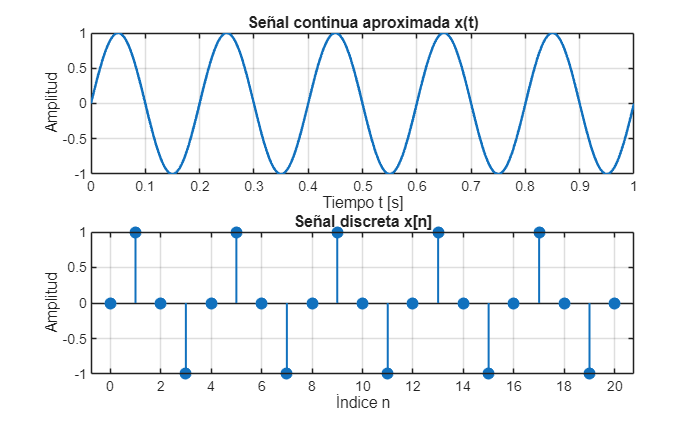

clc;
clear;
close all;

% Señal continua aproximada
t = 0:0.001:1;
x_t = sin(2*pi*5*t);

% Señal discreta
n = 0:20;
Fs = 20;
x_n = sin(2*pi*5*n/Fs);

% Gráfica
figure;

subplot(2,1,1);
plot(t, x_t, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo t [s]');
ylabel('Amplitud');
title('Señal continua aproximada x(t)');

subplot(2,1,2);
stem(n, x_n, 'filled', 'LineWidth', 1.2);
grid on;
xlabel('Índice n');
ylabel('Amplitud');
title('Señal discreta x[n]');

## Interpretación del Ejemplo 1

La primera gráfica muestra una señal definida sobre un eje temporal continuo aproximado. La segunda gráfica muestra una secuencia discreta, donde la señal existe únicamente en instantes de muestreo.

En telecomunicaciones, una señal de voz es continua antes de ser digitalizada; luego, al ser muestreada, se convierte en una secuencia discreta de valores.

## 2.3 Señales analógicas y señales digitales

Una señal analógica es continua en el tiempo y puede tomar infinitos valores de amplitud dentro de un intervalo. Una señal digital, en cambio, es discreta en el tiempo y además posee amplitudes cuantizadas.

La digitalización de una señal implica dos procesos principales:

- Muestreo: discretización del tiempo.

- Cuantización: discretización de la amplitud.

## Ejemplo 2: Señal analógica aproximada y señal digital cuantizada

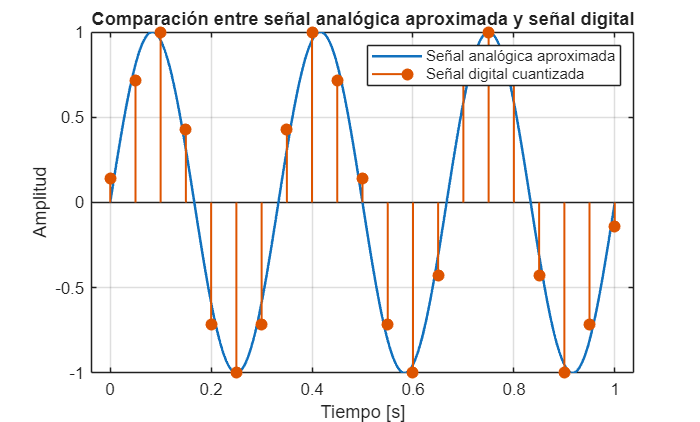

clc;
clear;
close all;

% Señal analógica aproximada
t = 0:0.001:1;
x_analogica = sin(2*pi*3*t);

% Muestreo
Fs = 20;
n = 0:Fs;
t_m = n/Fs;
x_muestreada = sin(2*pi*3*t_m);

% Cuantización simple a pocos niveles
niveles = 8;
x_digital = round((x_muestreada + 1)*(niveles-1)/2);
x_digital = 2*x_digital/(niveles-1) - 1;

% Gráfica
figure;
plot(t, x_analogica, 'LineWidth', 1.5);
hold on;
stem(t_m, x_digital, 'filled', 'LineWidth', 1.2);
grid on;

xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Comparación entre señal analógica aproximada y señal digital');
legend('Señal analógica aproximada', 'Señal digital cuantizada');

## Interpretación del Ejemplo 2

La señal digital no reproduce todos los valores posibles de la señal analógica, sino que utiliza un número limitado de niveles de amplitud. Este proceso permite almacenar y procesar la señal mediante sistemas digitales, aunque introduce un error de cuantización.

## 2.4 Señales periódicas y no periódicas

Una señal continua x(t) es periódica si existe un valor positivo T0 tal que x(t) = x(t + T0), para todo valor de t.

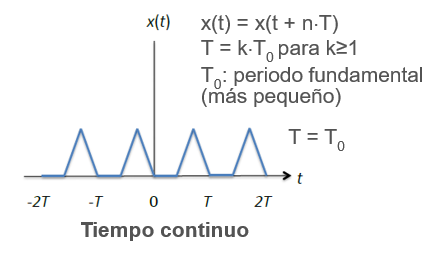

Una señal discreta x[n] es periódica si existe un entero positivo N0 tal que x[n] = x[n + N0], para todo valor entero de n.

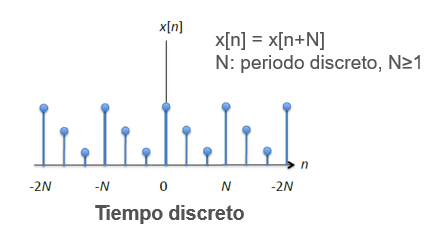

Si no existe tal periodo, la señal se considera no periódica.

## Ejemplo 3: Señal periódica y señal no periódica

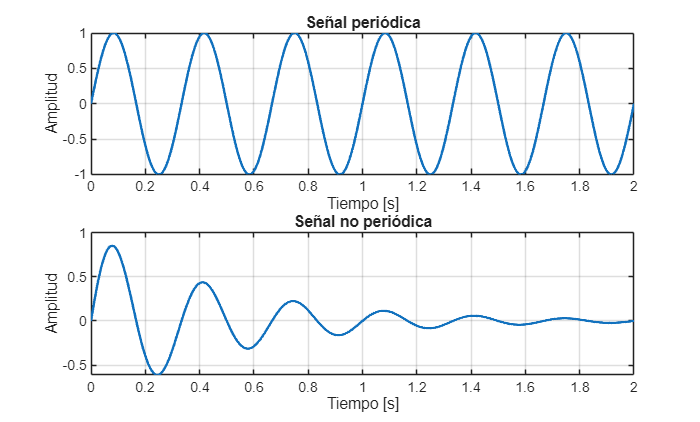

clc;
clear;
close all;

t = 0:0.001:2;

% Señal periódica
x_periodica = sin(2*pi*3*t);

% Señal no periódica
x_no_periodica = exp(-2*t).*sin(2*pi*3*t);

% Gráfica
figure;

subplot(2,1,1);
plot(t, x_periodica, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Señal periódica');

subplot(2,1,2);
plot(t, x_no_periodica, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Señal no periódica');

## Interpretación del Ejemplo 3

La señal sinusoidal conserva su forma en intervalos regulares de tiempo, por lo que es periódica. En cambio, la segunda señal presenta una amplitud decreciente debido al factor exponencial, por lo que no repite exactamente su forma y se clasifica como no periódica.

## 2.5 Señales pares e impares

Una señal es par si cumple x(t) = x(-t). En tiempo discreto: x[n] = x[-n].

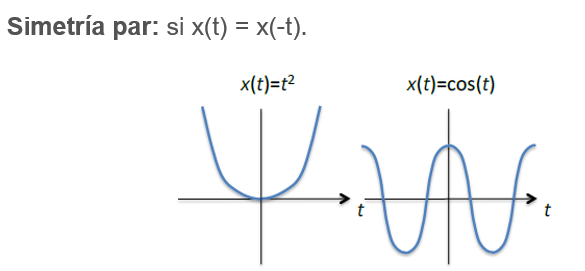

Una señal es impar si cumple x(t) = -x(-t). En tiempo discreto: x[n] = -x[-n].

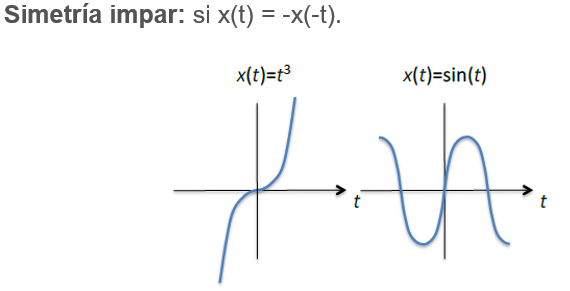

Toda señal puede descomponerse como la suma de una componente par y una componente impar.

## Ejemplo 4: Señal par y señal impar

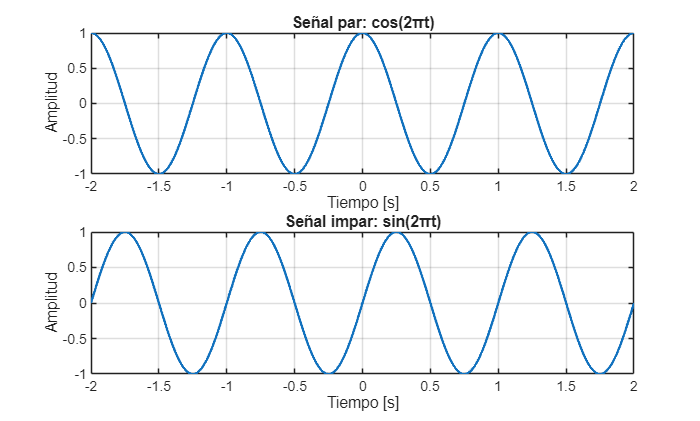

clc;
clear;
close all;

t = -2:0.001:2;

% Señal par
x_par = cos(2*pi*t);

% Señal impar
x_impar = sin(2*pi*t);

% Gráfica
figure;

subplot(2,1,1);
plot(t, x_par, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Señal par: cos(2πt)');

subplot(2,1,2);
plot(t, x_impar, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Señal impar: sin(2πt)');

## Interpretación del Ejemplo 4

La función coseno es simétrica respecto al eje vertical, por lo que es una señal par. La función seno presenta simetría respecto al origen, por lo que es una señal impar.

## Ejemplo 5: Descomposición de una señal en parte par e impar

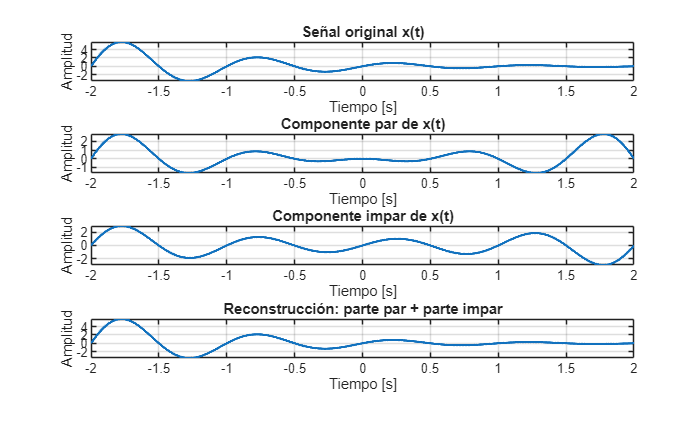

clc;
clear;
close all;

t = -2:0.001:2;

% Señal original
x = exp(-t).*sin(2*pi*t);

% Evaluación de x(-t)
x_menos_t = exp(t).*sin(-2*pi*t);

% Parte par e impar
x_parte_par = (x + x_menos_t)/2;
x_parte_impar = (x - x_menos_t)/2;

% Verificación
x_reconstruida = x_parte_par + x_parte_impar;

% Gráfica
figure;

subplot(4,1,1);
plot(t, x, 'LineWidth', 1.5);
grid on;
title('Señal original x(t)');
xlabel('Tiempo [s]');
ylabel('Amplitud');

subplot(4,1,2);
plot(t, x_parte_par, 'LineWidth', 1.5);
grid on;
title('Componente par de x(t)');
xlabel('Tiempo [s]');
ylabel('Amplitud');

subplot(4,1,3);
plot(t, x_parte_impar, 'LineWidth', 1.5);
grid on;
title('Componente impar de x(t)');
xlabel('Tiempo [s]');
ylabel('Amplitud');

subplot(4,1,4);
plot(t, x_reconstruida, 'LineWidth', 1.5);
grid on;
title('Reconstrucción: parte par + parte impar');
xlabel('Tiempo [s]');
ylabel('Amplitud');

## 2.6 Señales determinísticas y aleatorias

Una señal determinística se puede describir mediante una expresión matemática conocida o mediante una regla definida.

Una señal aleatoria no puede predecirse exactamente para todo instante de tiempo, aunque puede analizarse mediante herramientas estadísticas.

En telecomunicaciones, el ruido térmico, las interferencias y ciertas fluctuaciones de sensores suelen modelarse como señales aleatorias.

## Ejemplo 6: Señal determinística y señal aleatoria

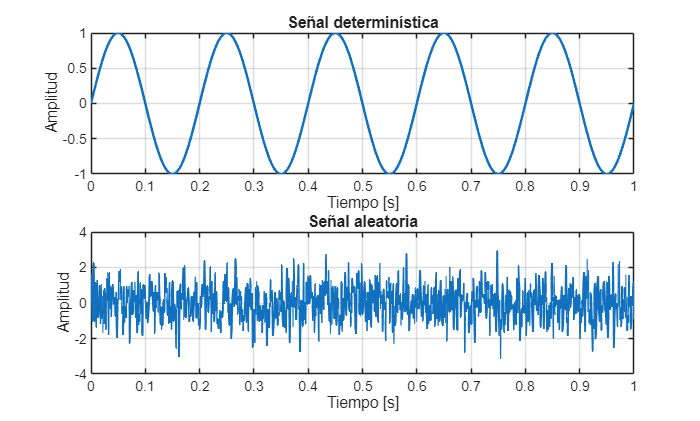

clc;
clear;
close all;

t = 0:0.001:1;

% Señal determinística
x_deterministica = sin(2*pi*5*t);

% Señal aleatoria
x_aleatoria = randn(size(t));

% Gráfica
figure;

subplot(2,1,1);
plot(t, x_deterministica, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Señal determinística');

subplot(2,1,2);
plot(t, x_aleatoria, 'LineWidth', 1.2);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Señal aleatoria');

## Interpretación del Ejemplo 6

La señal determinística sigue una expresión conocida, mientras que la señal aleatoria cambia de forma no predecible. Las señales aleatorias pueden analizarse mediante media, varianza, desviación estándar, correlación y densidad espectral de potencia.

## 2.7 Señales de energía y señales de potencia

La energía de una señal continua se define como la integral del módulo cuadrado de la señal en todo el tiempo.

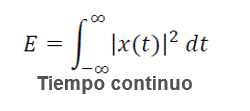

La energía de una señal discreta se define como la sumatoria del módulo cuadrado de la señal.

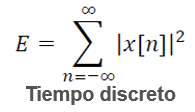

Una señal de energía tiene energía finita y potencia promedio igual a cero. Una señal de potencia tiene potencia finita y energía infinita.

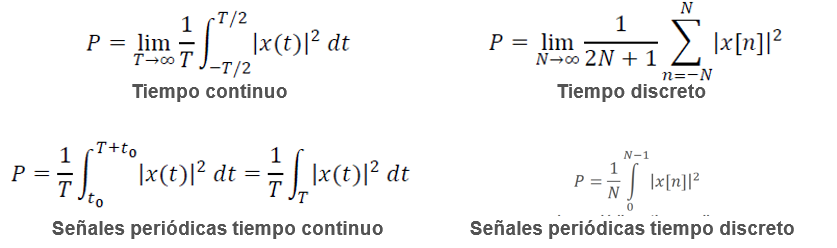

## Ejemplo 7: Aproximación de energía de una señal finita

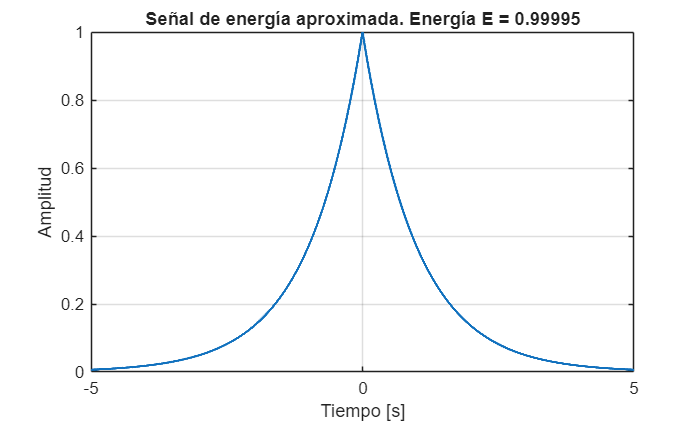

clc;
clear;
close all;

t = -5:0.001:5;
dt = t(2)-t(1);

% Señal finita aproximada
x = exp(-abs(t));

% Energía aproximada mediante suma numérica
E = sum(abs(x).^2)*dt;

% Gráfica
figure;
plot(t, x, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(['Señal de energía aproximada. Energía E = ', num2str(E)]);


disp(['Energía aproximada de la señal: ', num2str(E)]);

Energía aproximada de la señal: 0.99995


## Ejemplo 8: Aproximación de potencia de una señal periódica

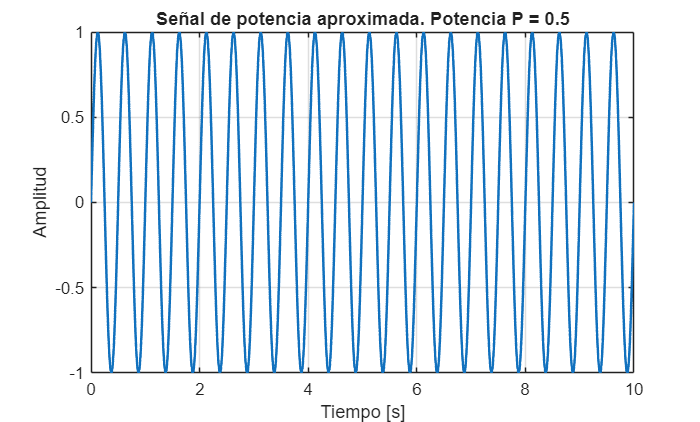

clc;
clear;
close all;

t = 0:0.001:10;
dt = t(2)-t(1);

% Señal periódica
x = sin(2*pi*2*t);

% Potencia promedio aproximada
P = (1/(t(end)-t(1))) * sum(abs(x).^2)*dt;

% Gráfica
figure;
plot(t, x, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(['Señal de potencia aproximada. Potencia P = ', num2str(P)]);


disp(['Potencia promedio aproximada: ', num2str(P)]);

Potencia promedio aproximada: 0.5


## Interpretación de los ejemplos de energía y potencia

La señal exponencial decreciente tiene energía finita porque su amplitud disminuye conforme aumenta el tiempo. En cambio, la señal sinusoidal ideal mantiene su oscilación indefinidamente; por ello, se analiza como señal de potencia.

## 2.8 Aplicación en telecomunicaciones

En telecomunicaciones, clasificar señales permite seleccionar técnicas adecuadas para transmisión, filtrado, modulación, muestreo y análisis espectral.

Algunos ejemplos:

- Una portadora senoidal se clasifica como señal continua, periódica, determinística y de potencia.

- Una señal de audio digitalizada se clasifica como discreta y digital.

- El ruido en un canal de comunicación se clasifica como señal aleatoria.

- Un pulso transmitido en un sistema digital puede analizarse como señal de energía.

## Ejemplo 9: Señal de telecomunicaciones con ruido

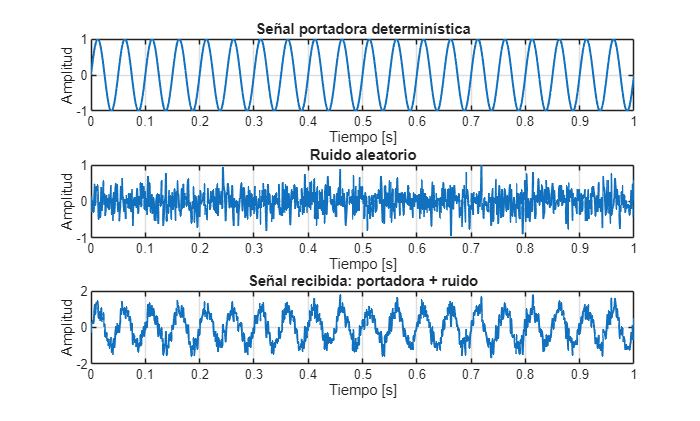

clc;
clear;
close all;

t = 0:0.001:1;

% Señal portadora determinística
portadora = sin(2*pi*20*t);

% Ruido aleatorio
ruido = 0.3*randn(size(t));

% Señal recibida
senal_recibida = portadora + ruido;

% Gráfica
figure;

subplot(3,1,1);
plot(t, portadora, 'LineWidth', 1.2);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Señal portadora determinística');

subplot(3,1,2);
plot(t, ruido, 'LineWidth', 1.2);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Ruido aleatorio');

subplot(3,1,3);
plot(t, senal_recibida, 'LineWidth', 1.2);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Señal recibida: portadora + ruido');

## Actividades propuestas

1. Genere una señal continua sinusoidal de 10 Hz y clasifíquela según los criterios estudiados. 

2. Genere una señal discreta usando stem y explique por qué no debe graficarse únicamente con plot. 

3. Cree una señal periódica y una señal no periódica en MATLAB. 

4. Demuestre gráficamente que cos(t) es una señal par y que sin(t) es una señal impar. 

5. Genere una señal aleatoria con randn y calcule su media y desviación estándar. 

6. Calcule de forma aproximada la energía de una señal exponencial decreciente. 

7. Calcule de forma aproximada la potencia de una señal sinusoidal. 

8. Explique cómo clasificaría una señal de audio capturada por un micrófono y luego almacenada en una computadora.

### Preguntas de reflexión

1. ¿Por qué es importante distinguir entre señal continua y señal discreta? 

2. ¿Qué diferencia existe entre una señal discreta y una señal digital? 

3. ¿Por qué una señal sinusoidal ideal se considera señal de potencia? 

4. ¿Qué tipo de señal representa mejor el ruido en un sistema de telecomunicaciones? 

5. ¿Qué ventaja tiene descomponer una señal en parte par e impar?

### Conclusiones

La clasificación de señales permite identificar propiedades esenciales que orientan su análisis matemático y computacional. Las señales pueden clasificarse según su dominio temporal, amplitud, periodicidad, simetría, naturaleza determinística o aleatoria, energía y potencia.

Esta clasificación tiene aplicaciones directas en telecomunicaciones, electrónica, control, procesamiento digital de señales, sensores e inteligencia artificial aplicada. MATLAB facilita la visualización de estas propiedades mediante simulaciones.

### Bibliografía básica

- Oppenheim, A. V., Willsky, A. S., & Nawab, S. H. Señales y sistemas.

- Lathi, B. P. Linear Systems and Signals.

- Haykin, S., & Van Veen, B. Signals and Systems.

- Proakis, J. G., & Manolakis, D. G. Digital Signal Processing.

- MathWorks Documentation. MATLAB Live Editor.